# 王智风速数据处理

clc;clear;close all;

## step1. 读取观测数据与实测数据

A=load('C:\Users\Kylin\Desktop\智先生\W_obs.mat');
B=load('C:\Users\Kylin\Desktop\智先生\W_ysu.mat');
W_obs=A.W_obs;
W_ysu=B.w_ysu;
[i,~]=size(W_obs);
[m,n]=size(W_ysu);
W_obs(i,:)=[];%统一矩阵行列
[i,j]=size(W_obs);%更新size

## Step2. 循环判读数据是否一样或者不一样或者无效数据，并返回目标元素的行列数据，进行存储

%预分配内存（相同数据索引行列）
Data_fit_POS=zeros(m*n,2);%两数据都大于0---positive number观测数据中行列坐标
Data_fit_NEG=zeros(m*n,2);%两数据都小于0---negative number观测数据中行列坐标
Data_Nofit=zeros(m*n,2);%两数据一正一负---Nofit观测数据中行列坐标
Data_NaN=zeros(m*n,2);%观测数据中为NaN的无效数据行列坐标
numfitpos=0;%两数据都大于0的数据个数
numfitneg=0;%两数据都小于0的数据个数
numnNOfit=0;%两数据一正一负的数据个数
numNaN=0;%观测数据中为NaN的数据个数
for a=1:i
    for b= 1:j
        tf=isnan(W_obs(a,b));
        if tf==0%如果观测数据有效，不是NaN的话
            if W_obs(a,b)>0 && W_ysu(a,b)>0%均为正符号的元素判断
                numfitpos=numfitpos+1;
                Data_fit_POS(numfitpos,1)=a;
                Data_fit_POS(numfitpos,2)=b;
            elseif W_obs(a,b)<0 && W_ysu(a,b)<0%均为负符号的元素判断
                numfitneg=numfitneg+1;
                Data_fit_NEG(numfitneg,1)=a;
                Data_fit_NEG(numfitneg,2)=b;
            elseif W_obs(a,b)*W_ysu(a,b)<0%不同符号的元素
                numnNOfit=numnNOfit+1;
                Data_Nofit(numnNOfit,1)=a;
                Data_Nofit(numnNOfit,2)=b;
            end

        else%如果观测数据无效，是NaN的话
            numNaN=numNaN+1;
            Data_NaN(numNaN,1)=a;
            Data_NaN(numNaN,2)=b;
            continue;%%如果观测数据无效，是NaN的话，就跳至下一个
        end
    end 
end 
%位置矩阵的未填充数据删除,仅保留有效行列坐标数据，方便画图
D=find(Data_fit_POS(:,1)==0);
Data_fit_POS(D,:)=[];
D=find(Data_fit_NEG(:,1)==0);
Data_fit_NEG(D,:)=[];
D=find(Data_Nofit(:,1)==0);
Data_Nofit(D,:)=[];
D=find(Data_NaN(:,1)==0);
Data_NaN(D,:)=[];

## Step3. 将矩阵元素分颜色分区域按照坐标索引画出

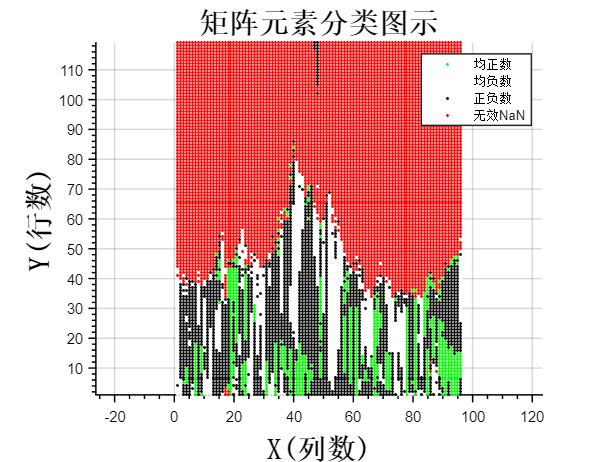

figure(1)%测点分类图
plot(Data_fit_POS(:,2),Data_fit_POS(:,1),'g.');hold on; axis equal;
plot(Data_fit_NEG(:,2),Data_fit_NEG(:,1),'w.');hold on; axis equal;
plot(Data_Nofit(:,2),Data_Nofit(:,1),'k.');hold on; axis equal;
plot(Data_NaN(:,2),Data_NaN(:,1),'r.');hold on; axis equal;
legend('均正数','均负数','正负数','无效NaN');
title('矩阵元素分类图示','fontSize',20,'FontName','宋体','FontWeight','bold');
xlabel('X(列数)','fontSize',20,'FontName','宋体','FontWeight','bold');
ylabel('Y(行数)','fontSize',20,'FontName','宋体','FontWeight','bold');
zlabel('Z(mm)','fontSize',20,'FontName','宋体','FontWeight','bold');
set(gca, 'Box', 'off', ...                                                         % 边框
        'LineWidth', 1, 'GridLineStyle', '-',...                                   % 坐标轴线宽
        'XGrid', 'on', 'YGrid', 'on','ZGrid', 'on', ...                          % 网格
        'TickDir', 'out', 'TickLength', [.015 .015], ...                           % 刻度
        'XMinorTick', 'on', 'YMinorTick', 'on',  'ZMinorTick', 'on',...         % 小刻度
        'XColor', [0 0 0],  'YColor',[0 0 0], 'ZColor', [0 0 0]);         %坐标轴颜色  

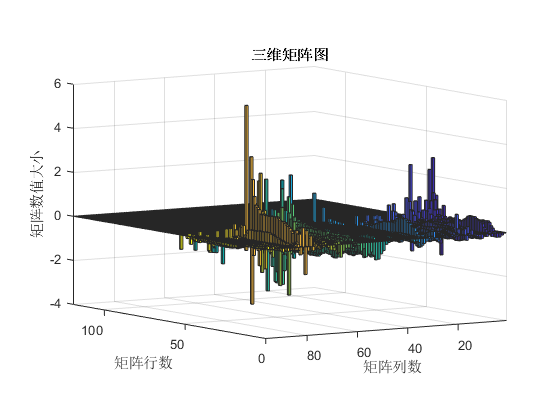

figure(2)%三维风场方向图
bar3(W_obs);
title("三维矩阵图")
xlabel("矩阵列数")
ylabel("矩阵行数")
zlabel("矩阵数值大小")
view([-212.55 6.41])